# Modelo 5

Modelo de crecimiento exponencial.


$$\begin{array}{l}
\frac{\mathrm{dM}}{\mathrm{dt}}=r\cdot M\\
\mathrm{con}\;M\left(t_o \right)=M_o 
\end{array}$$


#### 1. Resolución de la EDO

clc, clear
syms M(t) M0 t0 r

edo = diff(M, t, 1) == r*M;
cond = [M(t0)==M0];

M(t) = dsolve(edo, cond)

$$M(t) = M_{0}\,{\mathrm{e}}^{r\,t}\,{\mathrm{e}}^{-r\,t_{0}}$$

M(t) = collect(M(t), [r,t])     % para sacar factor comun

$$M(t) = M_{0}\,{\mathrm{e}}^{r\,t}\,{\mathrm{e}}^{-r\,t_{0}}$$

No hay un estado estacionario (equilibrio evidente).

El proceso es igual que el del modelo anterior con el signo negativo.

#### Tasa de duplicación: 

Tiempo que transcurre hasta que la cantidad física es el doble de la inicial.


$$M\left(t\right)=2\cdot M_o$$


tasa_dup = solve(M == 2*M0, t)

$$tasa\_dup = \frac{\log\left(2\,{\mathrm{e}}^{r\,t_{0}}\right)}{r}$$

#### 2. Sustitución de valores iniciales y constante r

r_values = [0.05, 0.1, 0.2];
ic_values = [0 1; 0 1; 0 1];
t_values = 0:5:100;
[m, n] = size(r_values);

#### 3. Gráfica para cada caso

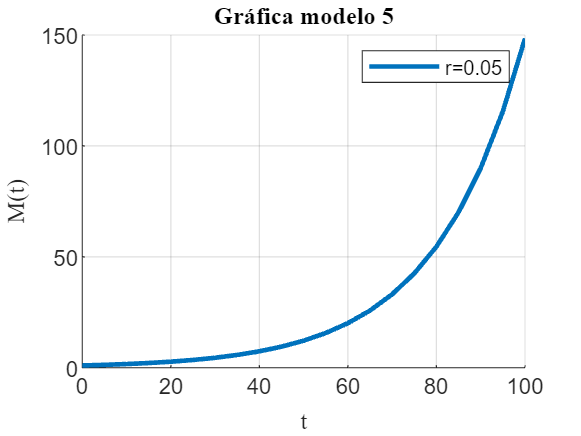

figure;
hold on;
for i = 1:1%n
    M_subs = subs(M, [r t0, M0], [r_values(i), ic_values(i,1), ic_values(i,2)]);
    
    % Evaluar la solución en los valores de tiempo dados
    M_values = subs(M_subs, t, t_values);
    
    % Graficar la solución
    plot(t_values, M_values, 'LineWidth', 2, 'DisplayName', ['r=' num2str(r_values(i))]);
end

xlabel('t','FontName','latex');
ylabel('M(t)','FontName','latex');
title('Gráfica modelo 5','FontName','latex');
legend('show');
grid on;
hold off;

Observamos que a mayor es la proporción del gasto, menos cantidad de dinero se ahorra (para r = 0.8, los valores de M(t) son menores).

#### 4. Estudio de estabilidad

Estabilidad es ocurre cuando $\frac{\textrm{dM}}{\textrm{dt}}=0$; sustituyo:

 
$$\begin{array}{l}
0=r\cdot M\\
M=0
\end{array}$$


syms M r
eq =r*M == 0;
M = solve(eq,M)

$$M = 0$$

Observamos en la gráfica que efectivamente se estabiliza, cuando $M=0$ en cualquiera de los casos. El estado estacionario o de equilibrio es **trivial**.

### Por circuito en Simulink

**Limpieza del entorno de trabajo**

clear     % limpieza del espacio de trabajo
clc       % limpieza de línea de comando
close all % cerrar todas las figuras

#### Configuración usuario 

Se muestran los ajustes elejidos por el usuario aplicables a cualquier modelo de simulación discreta. 

Configuración del solver

solver = struct();
solver.type = "Variable-Step";
solver.name = "ode45";
solver.start = 0;
solver.stop = 15;
solver.step = 1;

Nombre del modelo

model_name = "modelo3";

Condiciones iniciales y constantes del modelo:

k_values =  [0,0,0];
r_values = [0.4, 0.1, 0.3];
ic_values = [0 1; 0 1; 0 1];
t_values = 0:5:100;
[m, n] = size(k_values);

sim_config, función que simula el modelo de nombre model_name para una configuración de solver almacenada en el struct solver. Recibe como argumentos el nombre del modelo y un struct con la configuración del solver.

sim_data = sim_config(model_name, solver); % End of file definition

De sim_data se extrae la información de la simulación gracias a bloques output.

Obtenemos un data set con las señales del campo yout

signals = sim_data.yout;
M1 = signals{1}.Values.Data

M1 =     0.4000    0.1000    0.3000
    0.4510    0.1030    0.3283
    0.5085    0.1062    0.3592
    0.5733    0.1094    0.3930
    0.6464    0.1127    0.4300
    0.7288    0.1162    0.4705
    0.8218    0.1197    0.5148
    0.9265    0.1234    0.5633
    1.0447    0.1271    0.6163
    1.1779    0.1310    0.6744


M = signals{2}.Values.Data

M =     1.0000    1.0000    1.0000
    1.1275    1.0305    1.0942
    1.2712    1.0618    1.1972
    1.4333    1.0942    1.3100
    1.6161    1.1275    1.4333
    1.8221    1.1618    1.5683
    2.0544    1.1972    1.7160
    2.3164    1.2337    1.8776
    2.6117    1.2712    2.0544
    2.9447    1.3100    2.2479


signal_time = signals{1}.Values.Time;

#### Gráfica 1

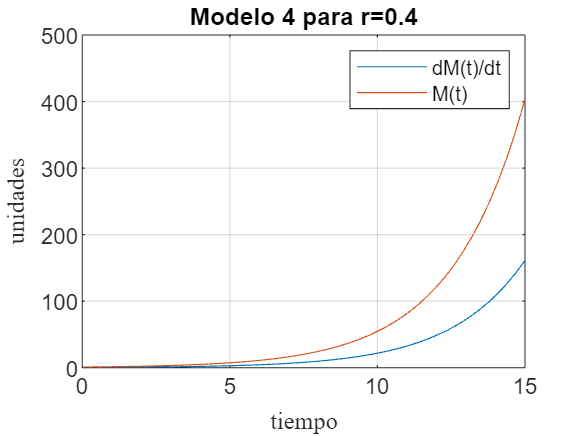

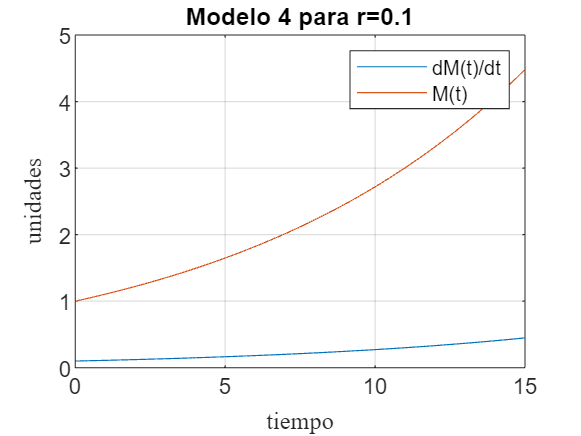

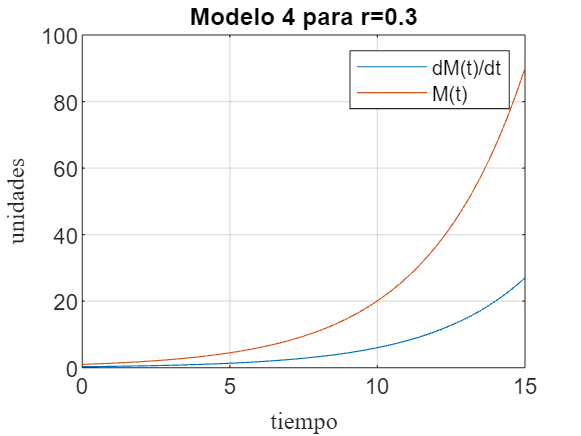

[m, n] = size(M1);
for i =1:n
    figure
    plot(signal_time, M1(:,i))
    hold on
    plot(signal_time, M(:,i))
    grid on
    xlabel("tiempo","FontName","latex");
    ylabel("unidades","FontName","latex");
    title(['Modelo 4 para r=' num2str(r_values(i))]);
    legend('dM(t)/dt','M(t)');
    hold off
end 

#### Gráfica 2

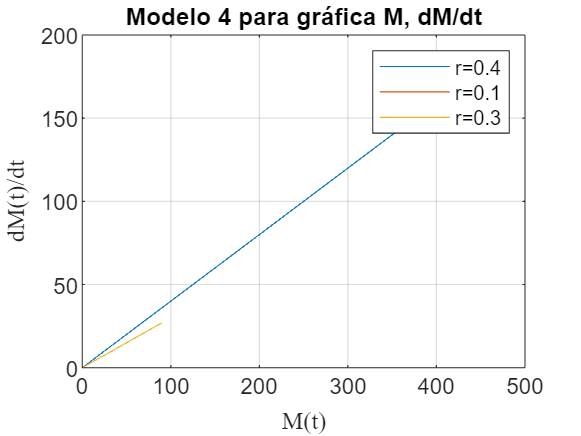

[m, n] = size(M1);
figure
for i =1:n
    plot(M(:,i), M1(:,i), 'DisplayName', ['r=' num2str(r_values(i))])
    grid on
    xlabel("M(t)","FontName","latex");
    ylabel("dM(t)/dt","FontName","latex");
    title('Modelo 4 para gráfica M, dM/dt');
    hold on
end 
legend('show')

### ***Funciones disponibles para todas las secciones***

MATLAB permite utilizar la última sección de un livescript para definir funciones globales.

**Decorador de la función sim de MATLAB**

Esta función ejecuta la función sim, tras establecer los parámetros del solver. Recibe como argumentos el nombre del modelo y un struct con la configuración del solver.

function sim_data = sim_config(model_name, solver)

Carga del modelo con load_system

load_system(model_name)
% open_system(model_name) will also open it

Configuración con set_param

% Set solver parameters
set_param(model_name, ...
    SolverType  = solver.type, ...
    SolverName  = solver.name, ...
    StartTime   = string(solver.start),...
    StopTime    = string(solver.stop), ...
    FixedStep   = string(solver.step) ...
    )
% More model parameters can be retrieved with:
% model_data = get_param(model_name, "ObjectParameters")
% Access blocks params with "model_name/block_name"

Simulación del modelo con sim

sim_data = sim(model_name);
% SimulationMode="normal" by default
end

Se utiliza el bloque Out1 para cada señal.